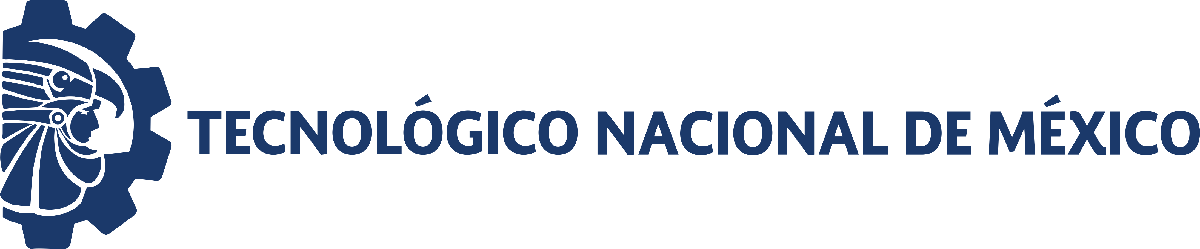                                 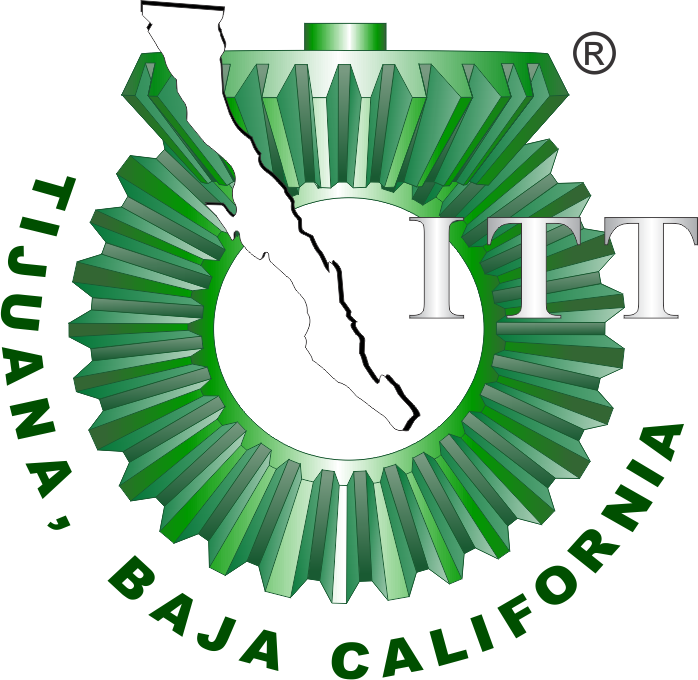

# Práctica tres: Modelado y control de sistemas musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

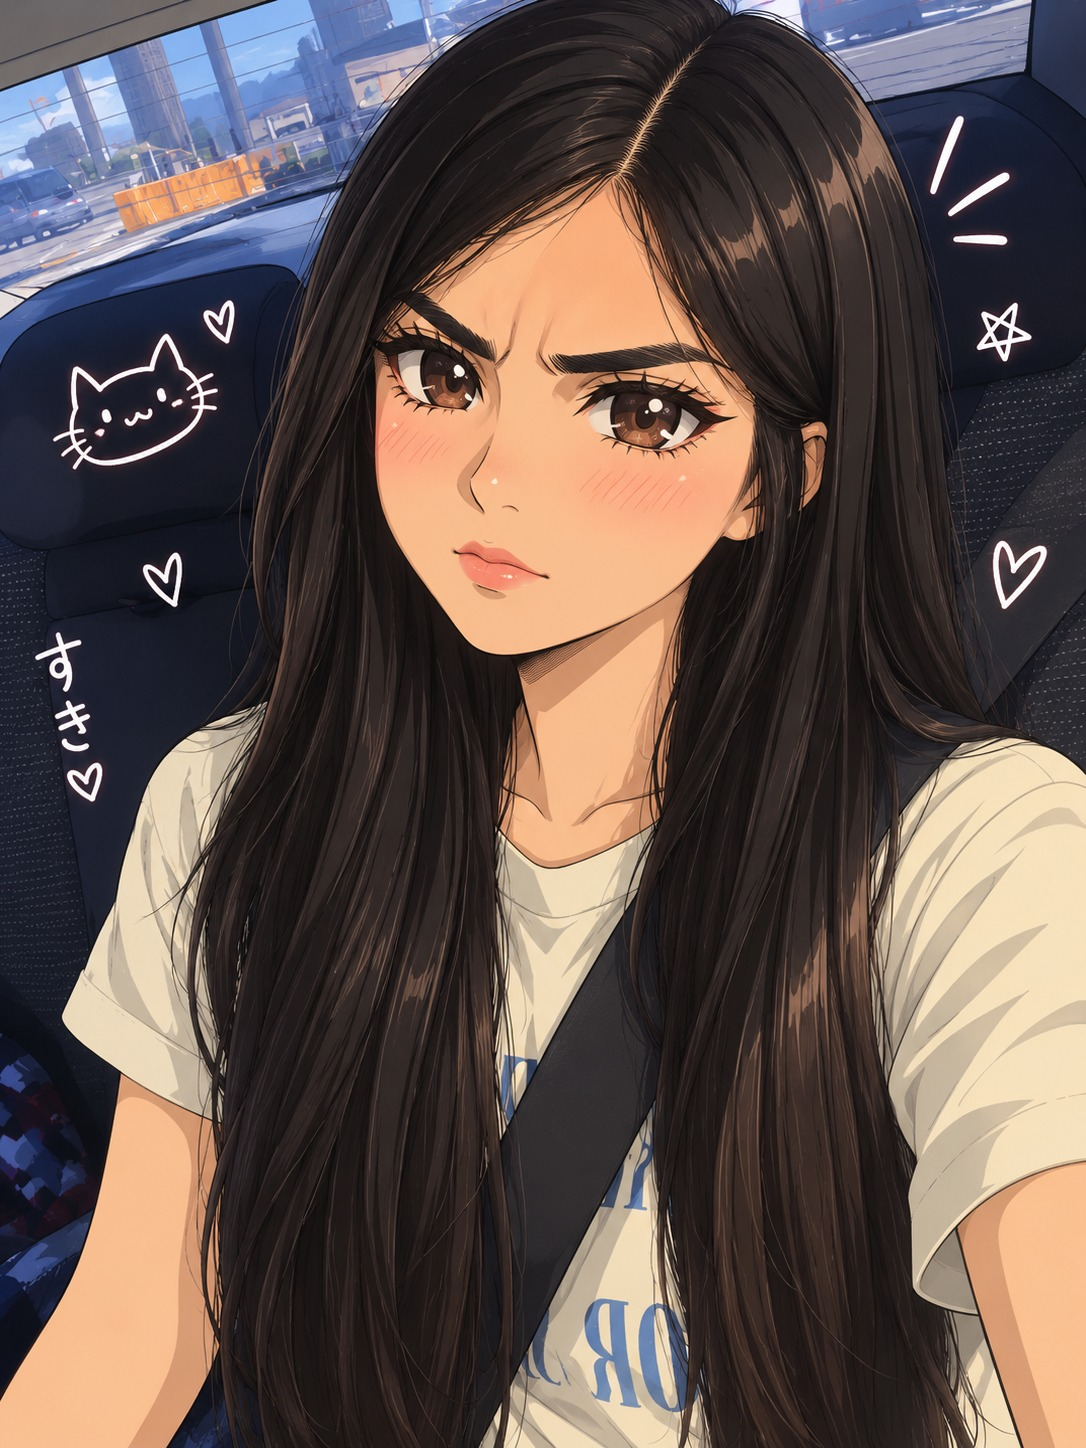

Nombre del alumno: Briseida Prado Acosta

Número de control: 23210715

Correo institucional: 23210715**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file= 'Prado23210715P3';
open_system('Prado23210715P3');
parameters.StopTime='15';
parameters.Solver='ode15s';
parameters.MaxStep='1E-3';
x=sim('Prado23210715P3',parameters);

## **Respuesta del sistema**

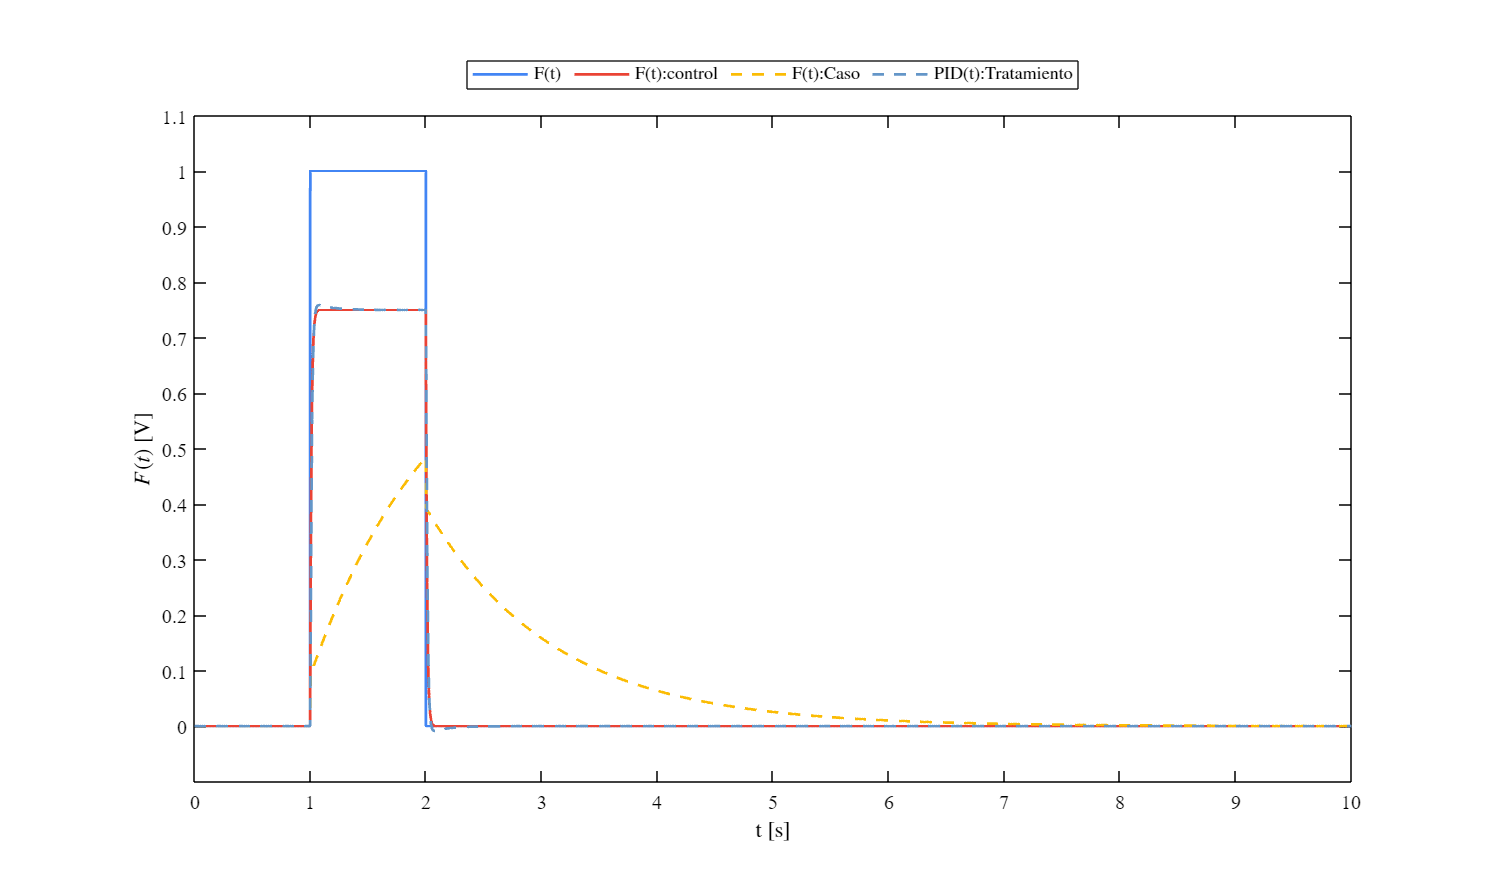

plotsignals(x.t,x.F,x.control,x.Fsy,x.PID, 'impulso unitario')

## Función: respuesta de la simulación

function plotsignals(t,F,control,Fsy,PID,signal)
set(figure(),'Color','w')
set(gcf,'Units','inches','position',[0.5,0.5,12,7])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
clr1 = [66, 133, 244]/255;
clr2 = [234, 67, 53]/255;
clr3 = [251, 188, 5]/255;
clr4 = [100, 150, 200]/255;
order = [clr1;clr2;clr3;clr4]; colororder (order)
xlabel('t [s]','interpreter','latex')
ylabel('$F (t)$ [V]','interpreter','latex')
xlim([0 10]); xticks (0:1:10)
ylim([-0.1 1.1]); yticks(0:0.1:1.1)

if signal == "impulso unitario"
    plot (t,F, '-', t, control,'-', t,Fsy,'--',t,PID,'--','LineWidth',1.5, 'MarkerSize', 5, 'MarkerIndices', ...
        1:1e3:length(t));

    L= legend ('F(t)','F(t):control','F(t):Caso','PID(t):Tratamiento');
     set(L,'interpreter','latex','location','northoutside','orientation', 'horizontal')
 
end

set(gcf, 'color', 'white')
set(gca, 'color', 'white', 'Xcolor','black','yColor','black')
set(L,'Color','white','TextColor','black')
exportgraphics(gcf,'Sistemamusculoesqueletico.pdf','ContentType','vector')
end    